# Getting Started with MATLAB (Matrices & Arrays)

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-11-20

## Matrices and Arrays

Array creation, combining, reshaping, rearranging, and indexing

Please refer to this: [https://www.mathworks.com/help/matlab/matrices-and-arrays.html](https://www.mathworks.com/help/matlab/matrices-and-arrays.html)

### Part 1: Create Arrays

% define an inline function to evaluate and print out true or false
logicStr = {'False', 'True'};
PrtEqual = @(M1Str, M1, M2Str, M2) fprintf('%s and %s are equal: %s.', M1Str, M2Str, logicStr{isequal(M1, M2)+1});

% example of how to use PrtEqual
PrtEqual('A', 1, 'B', 1) % True

A and B are equal: True.

PrtEqual('A', 1, 'B', 2) % False

A and B are equal: False.


% zeros and ones
M1 = zeros(5,5);
M2 = ones(5,5);
PrtEqual('M1', M1, 'M2-1', M2-1);

M1 and M2-1 are equal: True.


% ones and repmat
M3 = ones(10,10);
M4 = repmat(M2,2,2);
PrtEqual('M3', M3, 'M4', M4);

M3 and M4 are equal: True.


% eye and diag
M5 = eye(5,5);
M6 = diag(ones(5,1));
PrtEqual('M5', M5, 'M6', M6); clear;

M5 and M6 are equal: True.


% Q: Generate M3 and M5 using for-loop(s)

### Part 2: Create Grids and Indexing

clear;

% define an inline function to print out true or false
logicStr = {'False', 'True'};
PrtEqual = @(M1Str, M1, M2Str, M2) fprintf('%s and %s are equal: %s.', M1Str, M2Str, logicStr{isequal(M1, M2)+1});

% linespace
V1 = 2:2:10;
V2 = linspace(2,10,5);
PrtEqual('V1', V1, 'V2', V2);

V1 and V2 are equal: True.

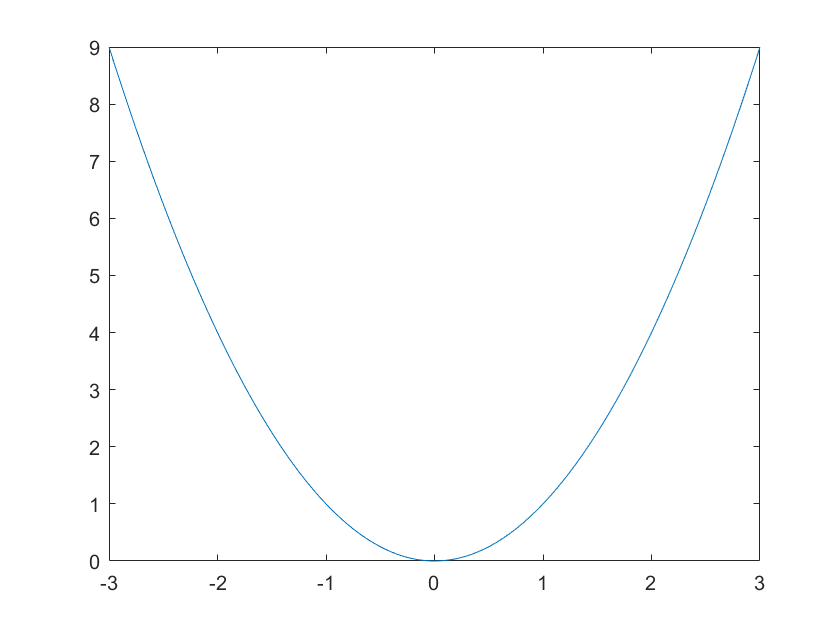


% draw y = x^2; xlim([-3,3]);
x = linspace(-3,3);
y = x.*x;
figure;plot(x,y);


% meshgrid and ind2sub 
msiz = [10 5];
[mX, mY] = meshgrid(1:msiz(2), 1:msiz(1));

[ir, ic] = ind2sub(msiz, 1:prod(msiz)); % prod(msiz) = msiz(1) * msiz(2)

ir = reshape(ir, msiz);
ic = reshape(ic, msiz);

PrtEqual('mX', mX, 'ic', ic);

mX and ic are equal: True.

PrtEqual('mY', mY, 'ir', ir);

mY and ir are equal: True.


% sub2ind and ind2sub are very useful in image processing operations. 
% sub2ind
M5 = eye(5,5);
indM7 = sub2ind(size(M5), 1:5, 1:5); % print indM7
M7 = zeros(size(M5));
M7(indM7) = 1;
PrtEqual('M5', M5, 'M7', M7);

M5 and M7 are equal: True.


% ind2sub
[I, J] = ind2sub(size(M7), find(M7));
PrtEqual('I', I', '1:5', 1:5);

I and 1:5 are equal: True.

PrtEqual('J', J', '1:5', 1:5);

J and 1:5 are equal: True.

### Part 3: Combine and Transform Array

clear;

% define an inline function to print out true or false
logicStr = {'False', 'True'};
PrtTrue = @(MStr, M) fprintf('%s is %s.', MStr, logicStr{M+1});
PrtEqual = @(M1Str, M1, M2Str, M2) fprintf('%s and %s are equal: %s.', M1Str, M2Str, logicStr{isequal(M1, M2)+1});

% cat, horzcat, vertcat
M8 = reshape(1:25, 5, 5);
M9 = horzcat(M8, M8);
M10 = cat(2,M8,M8);
M11 = repmat(M8, 1,2);
PrtEqual('M9', M9, 'M10', M10);

M9 and M10 are equal: True.

PrtEqual('M9', M9, 'M11', M11);

M9 and M11 are equal: True.


M12 = vertcat(M8, M8);
M13 = cat(1,M8,M8);
M14 = repmat(M8,2,1);
PrtEqual('M12', M12, 'M13', M13);

M12 and M13 are equal: True.

PrtEqual('M13', M13, 'M14', M14);

M13 and M14 are equal: True.


% repelem
M15 = cat(2, ones(3,3), ones(3,3)+1);
M15 = cat(1,M15,M15+2);
M16 = repelem([1 2;3 4], 3,3);
PrtEqual('M15', M15, 'M16', M16);

M15 and M16 are equal: True.


M = reshape(1:25, 5, 5);
% flip, fliplr, flipud
PrtEqual('flip(M,1)', flip(M,1),'flipud(M)', flipud(M));

flip(M,1) and flipud(M) are equal: True.

PrtEqual('flip(M,2)', flip(M,2),'fliplr(M)', fliplr(M));

flip(M,2) and fliplr(M) are equal: True.


% transpose, rot90
PrtEqual('transpose(M)', transpose(M),'fliplr(rot90((M))', flipud(rot90((M))));

transpose(M) and fliplr(rot90((M)) are equal: True.

PrtEqual('rot90(M)', rot90(M),'transpose(fliplr((M)))', transpose(fliplr((M))));

rot90(M) and transpose(fliplr((M))) are equal: True.

### Part 4: Determine Size and Shape

% length, numel, size
x = rand(3,5);
sx1 = length(x);
size_x = size(x);
[~, I] = max(size_x);
sx2 = size(x,I);
PrtEqual('sx1', sx1, 'sx2', sx2);

sx1 and sx2 are equal: True.


V2 = rands(5,1);
PrtEqual('length(V2)', length(V2), 'numel(V2)', numel(V2));

length(V2) and numel(V2) are equal: True.


% ismatrix ⊃ isvector ⊃ isscalar
a = 1;
PrtTrue('isscalar(a)', isscalar(a));

isscalar(a) is True.

PrtTrue('isvector(a)', isvector(a));

isvector(a) is True.

PrtTrue('ismatrix(a)', ismatrix(a));

ismatrix(a) is True.


vec = [1 2 3];
PrtTrue('isscalar(vec)', isscalar(vec));

isscalar(vec) is False.

PrtTrue('isvector(vec)', isvector(vec));

isvector(vec) is True.

PrtTrue('ismatrix(vec)', ismatrix(vec));

ismatrix(vec) is True.


matc = [1 2 3; 4 5 6];
PrtTrue('isscalar(matc)', isscalar(matc));

isscalar(matc) is False.

PrtTrue('isvector(matc)', isvector(matc));

isvector(matc) is False.

PrtTrue('ismatrix(matc)', ismatrix(matc));

ismatrix(matc) is True.


% isrow, iscoloumn, size
c = rand(1,5);
PrtEqual('isrow(c)', isrow(c), 'size(c,1)==1', size(c,1)==1);

isrow(c) and size(c,1)==1 are equal: True.


d = rand(5,1);
PrtEqual('iscolumn(d)', iscolumn(d), 'size(d,2)==1', size(d,2)==1);

iscolumn(d) and size(d,2)==1 are equal: True.

## Exercise

### Exercise 001

### Write a code to generate the following matrix

    0     1     0     0     0     0

    0     0     1     0     0     0

    0     0     0     1     0     0

    0     0     0     0     1     0

    0     0     0     0     0     1

    0     0     0     0     0     0

### Exercise 002

### Write a code to generate M1~M9

**(a) Use for-loop(s) if needed.**

**(b) Only use the functions above.**